# 问题7 确定材料来源

## 7.0 模型假设

- 在一定时间和环境范围内，材料磨损规律相对稳定；

- 同一来源的材料具有相似的物理、化学特性；忽略一些微小的、对整体判断影响不大的随机因素。

## 7.1 模型建立：基于熵权法的相似度评价

相关宏观物理特性有：

- 密度

- 硬度

- 颜色（采用颜色编码）

- 纹理（计算机处理，得到均方误差）

- 结构

相关的地理信息有：

- 推测材料产地到材料发现地之间的距离（将楼梯自身的这一指标设为0）

- 推测材料产地到材料发现地之间的地形复杂度（将楼梯自身的这一指标设为0）

相关的历史信息有：

- 文献记载，转换为推测的置信度（将楼梯自身的这一指标设为1）

建模步骤：

- 假设可以给出m个推断，每个推断中有n个指标，则可以为每个推测建立一个特征向量$K_i = (k_1, k_2, ..., k_n)$，楼梯所用的材料自身也根据各指标建立一个特征向量

- 为避免各指标间绝对数值相差过大，将上述$m+1
$个特征向量合成一$(m+1)\times n$的矩阵$K$，对每个指标（即每列）进行归一化得到新的矩阵$K^{\rm{norm}}$，即$K_{ij}^{\rm{norm}}=\frac{K_{ij}}{\sum_{i=1}^{m+1}K_{ij}}$

- 用熵权法给每个指标赋权：1）计算第j项指标的熵$e_j=-\frac{1}{\ln{(m+1)}}\sum_{i=1}^{m+1} K^{\rm{norm}}_{ij}\ln K^{\rm{norm}}_{ij}$；2）计算第j项指标的变异系数$g_j=1-e_j$；3）计算第j项指标的权重为$w_j=\frac{g_j}{\sum_{j=1}^{m+1}g_j}$

- 用添加熵权后的欧氏距离的倒数定义各样本与楼梯所用材料$K^{\rm{norm}}_0$之间的相似度为：$S(K^{\rm{norm}}_i, K^{\rm{norm}}_0)=\frac{1}{1+\sqrt{\sum_{j=1}^n w_j(K^{\rm{norm}}_{ij}-K^{\rm{norm}}_{0j})^2}}$。计算各个样本与$L_0$之间的相似度。由定义可见，若预测完全符合$L_0$，相似度达到最大值1

- 按照相似度进行排序，可以给出一个评价排序，取相似度最高者，若其相似度大于90%（人为规定的阈值）则认为估计是可靠的

% 参数设置
infer = 8;    % 做出推断的数量
index = 8;    % 每个推断含有的指标

K = zeros(infer+1, index);
K = K+rand(infer+1, index);
K_volsum = sum(K, 1);
K_norm = zeros(infer+1, index);
for i = 1:(infer+1)
    for j = 1:index
        K_norm(i,j) = K(i,j)/K_volsum(j);
    end
end
variation = 1+1/log(infer+1)*sum(K_norm.*log(K_norm), 1);
weight = variation/sum(variation);
similar = zeros(infer+1, 1);
for i = 1:(infer+1)
    similar(i) = 1/(1+sqrt(sum(weight.*(K_norm(i,:)-K_norm(infer+1,:)).^2)));
end
disp(similar);

    0.9513
    0.9183
    0.9152
    0.8677
    0.8789
    0.8876
    0.9210
    0.9292
    1.0000



# 问题8 每天使用楼梯的人数及频率特征

## 8.0 模型假设

- 人们上下楼时，都倾向于走在楼梯的中间

- 假设有m阶楼梯，每阶楼梯最多能容纳n人（n>2）并排，定义楼梯上瞬时人流量＜m时为显著低频；瞬时人流量＞mn/2时为显著高频；介于两者中间则视为正常人流量

- 认为踩踏的中心点在横向上满足正态分布

## 8.1 模型建立

- 对每天使用人数的研究，由于在本问中只需要研究数量而无需像之前几问给出踩踏中心点的分布，所以直接研究磨损体积即可，有：$V=\sum_{x,y}d(x,y)\cdot S=(\sum_{x,y}\beta\alpha(x,y)\cdot S)\cdot n\cdot N$，其中V是总磨损体积，S是网格单元的面积，$\beta$是楼梯磨损深度和受力分布的比值，n为使用总天数（已在前问中算出）。于是有：$N=\frac{\sum_{x,y}d(x,y)}{n\sum_{x,y}\beta \alpha(x,y)}$

- 由于人流量越大，单个楼梯上同时站的人就会越多，所以经常以短时间高人流量的模式使用的楼梯的磨损情况的标准差会变大；反之则变小。为了用标准差大小衡量使用模式，定义$C=\frac{\sigma}{d_{avg}}$为踩踏的分散度（其中$d_{avg}=fd_0$是在楼梯面上的平均踩踏深度，只与踩踏次数有关，$d_0$表示单次踩踏的平均深度），分散度越大则越分散，可由此判断是短时间大流量还是长时间低流量的使用模式。

- 下分析C的边界值。由假设2，瞬时人流量为m时可以看作每阶楼梯上只有一人，由于一阶楼梯最多容纳n人，将一个人占用的横向距离视为$\frac{l}{n}$（l为楼梯长度）；由假设1，可以认为人们全都站在楼梯中央；根据假设3，由$3\sigma$原则，此处可以认为$3\sigma_1=\frac{l}{2n}$。同理，在顺势人流量达到mn/2时，每阶楼梯容纳n/2人，占用的总横向距离为$\frac{l}{2}$，由$3\sigma$原则，此处认为$3\sigma_2=\frac{l}{4}$。综上，在$C<\frac{l}{fd_0}\cdot \frac{1}{6n}$时认为楼梯主要以显著的长时间低流量模式使用；在$C>\frac{l}{fd_0}\cdot \frac{1}{12}$时认为楼梯主要以显著的短时间大流量模式使用；介于两者之间的认为人流量不显著高也不显著低。

## 8.2 模型应用

### 8.2.1 一天内使用楼梯的人数

% 产生仿真数据
load F.mat;
f_n = 60000; % 模拟踩踏次数
m = 120;    n = 32; % 网格大小
L1 = 1.5;   % 楼梯实际长度
delta_S = (L1/m)^2; % 网格面积
r_down = 0.5;   % 下行次数的占比
sigma_0 = m/8;
d_true = True(f_n, m, n, delta_S, r_down, sigma_0);

% 其他参数
days = 2000;   % 使用天数

d_0 = (alphal_2R(n/2, m/2, 1, m, n, delta_S, F2R)+...
    alphal_1R(n/2, m/2, 1, m, n, delta_S, F1R))/2;  % 踩踏一次的分布
N = sum(sum(d_true))/(days*sum(sum(d_0)));
disp(['每日使用人次为', num2str(N)]);

每日使用人次为29.9946


### 8.2.2 人流量的特征分析（短时大量/长期少量）

n_simultaneous = 4; % 每阶楼梯上最多同时容纳的人数

d_true_volsum = sum(d_true, 1); % 计算每列的和
d_true_volsum = d_true_volsum/sum(d_true_volsum);   % 归一化概率
x_avg = sum((1:m).*d_true_volsum)*L1/m; % 计算踩踏点横坐标的均值
sigma = sqrt(sum(((1:m)*L1/m-x_avg).^2.*d_true_volsum)/L1);
d_avg = sum(d_true_volsum)/m/n;    % 整个楼梯面上的平均踩踏深度
C = sigma/d_avg;    % 计算踩踏分散度
disp(['踩踏分散度为', num2str(C)]);

踩踏分散度为594.8949


d_0_avg = sum(sum(d_0))/m/n;
C_low = L1/d_avg/6/n_simultaneous;
C_high = L1/d_avg/12;
disp(['踩踏分散度低于', num2str(C_low), '视为人流量显著低，', '踩踏分散度高于',...
    num2str(C_high), '视为人流量显著高']);

踩踏分散度低于240视为人流量显著低，踩踏分散度高于480视为人流量显著高


disp('在题设标准差为m/8下，为显著高人流量');

在题设标准差为m/8下，为显著高人流量


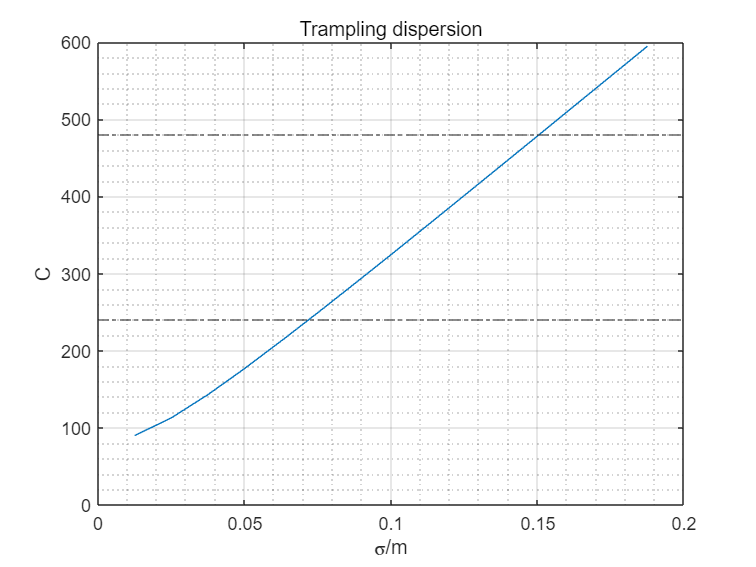


sigma_test = 1:m/8;
d_true_test = cell(length(sigma_test), 1);
C = zeros(length(sigma_test), 1);
for i = 1:length(sigma_test)
    d_true_test{i} = zeros(n, m);
    d_true_test{i} = True(f_n, m, n, delta_S, r_down, sigma_test(i));
    d_true_volsum_t = sum(d_true_test{i}, 1); % 计算每列的和
    d_true_volsum_t = d_true_volsum_t/sum(d_true_volsum_t);   % 归一化概率
    x_avg_t = sum((1:m).*d_true_volsum_t)*L1/m; % 计算踩踏点横坐标的均值
    sigma = sqrt(sum(((1:m)*L1/m-x_avg_t).^2.*d_true_volsum_t)/L1);
    d_avg = sum(d_true_volsum_t)/m/n;    % 整个楼梯面上的平均踩踏深度
    C(i,1) = sigma/d_avg;    % 计算踩踏分散度
end
figure();
plot(sigma_test*L1/m, C);
yline([C_low, C_high], '-.');
title('Trampling dispersion');
xlabel('\sigma/m');
ylabel('C');
grid on;grid minor;

function [d_true,f_1_true,f_2_true,U_1_true,U_2_true]=True(f_n,m,n,delta_S,r_down,sigma)
%规定有0<=r_down<=1
r_down=r_down*10;
load F.mat;
rng(42);
dot_true = zeros(f_n, 4);
f_1_true=zeros(n,m);
f_2_true=zeros(n,m);
for i=1:f_n
    dot_true(i,1) = round(normrnd(m/2, sigma));
    while dot_true(i,1)<1 || dot_true(i,1)>m    % 修改：为防止超出正态分布数据在楼梯两侧边缘累积，将超出边缘的数据重置
        dot_true(i,1) = round(normrnd(m/2, m/4));
    end

    dot_true(i,2) = round(normrnd(n/2-3, n/8));
    while dot_true(i,2)<1 || dot_true(i,2)>n-12
        dot_true(i,2) = round(normrnd(n/2-3, n/8));
    end

    triger=0 + (10-0)*rand;
    if triger<r_down %下行
        dot_true(i,3)=0;
    else %上行
        dot_true(i,3)=1;
    end

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    if dot_true(i,3)==1 %上行
        f_1_true(33-dot_true(i,2),dot_true(i,1))=f_1_true(33-dot_true(i,2),dot_true(i,1))+1;
    elseif dot_true(i,3)==0 %下行
        f_2_true(33-dot_true(i,2),dot_true(i,1))=f_2_true(33-dot_true(i,2),dot_true(i,1))+1;
    end
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    dot_true(i,4) = randi([0, 1]);% 1-左脚，0-右脚
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
U_1_true=sum(sum(f_1_true));
U_2_true=sum(sum(f_2_true));
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

d_true = zeros(n, m);
for i = 1:f_n
    if dot_true(i,3)&&dot_true(i,4) %上行，左脚
        d_true = d_true + alphal_1L(dot_true(i,2), dot_true(i,1),1,m,n,delta_S,F1L);
    elseif dot_true(i,3)&&(~dot_true(i,4)) %上行，右脚
        d_true = d_true + alphal_1R(dot_true(i,2), dot_true(i,1),1,m,n,delta_S,F1R);
    elseif (~dot_true(i,3))&&dot_true(i,4) %下行，左脚
        d_true = d_true + alphal_2L(dot_true(i,2), dot_true(i,1),1,m,n,delta_S,F2L);
    elseif (~dot_true(i,3))&&(~dot_true(i,4)) %下行，右脚
        d_true = d_true + alphal_2R(dot_true(i,2), dot_true(i,1),1,m,n,delta_S,F2R);
    end
end
end